e = Data.signals.e

e =     0.0377
    0.0283
    0.0314
    0.0377
    0.0408
    0.0377
    0.0377
    0.0377
    0.0377
    0.0377
    0.0377
    0.0408
    0.0377
    0.0377
    0.0377


e_max = max(e)

e_max = 0.0503

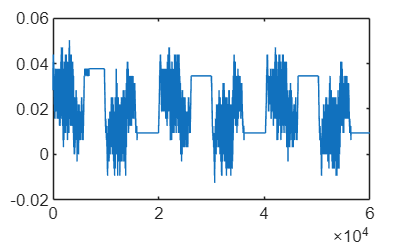

figure; plot(e);



Trun = 15

Trun = 15

N_samples = Trun*Fs; %measurement size per duration(samples)
T_terminate = 5;

Exercise = "ProtoLab_setup_45_2110";
Measurement = "methode2_fc_fv_fa";
SampleFreq = "fs_" + Fs + "_Hz";

ModelName = "Hardware_FFW";
[success, s1,s2,s3] = StartSignalMeasurement(p,N_samples,T_terminate,ModelName);

Starting the measurement, should take 15 seconds to collect 60000 Samples.
Measurement finished.
Retrieving measurement file(s).
Files retrieved.


if(~success)
    error("No measurement made!");
end

e_max = max(e)

e_max = 0.0691

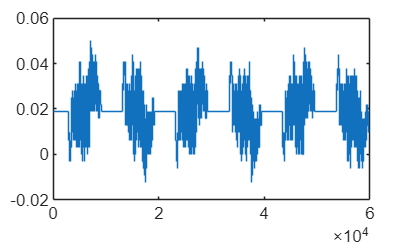

e = s1;
a_ref = s2;

figure; stairs(e); 

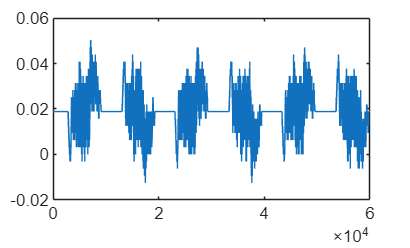

figure; plot(e);


Path = "FFW_Data/"  ...
        + Exercise ...
        + "/" + SampleFreq;

measurementName = Measurement + "_T" + Trun + "_S" + N_samples;
saveMeasurement(...
struct("runtime", Trun, "fs", Fs, "samples", N_samples), ...%settings    
struct("a_ref", a_ref,"e",e), ... %signals
struct([]),...
Path + '/FFW_Data/'+ measurementName);



